Adjusting GYRO dimensions.
Adjusting ACCEL dimensions.


Generating plots...


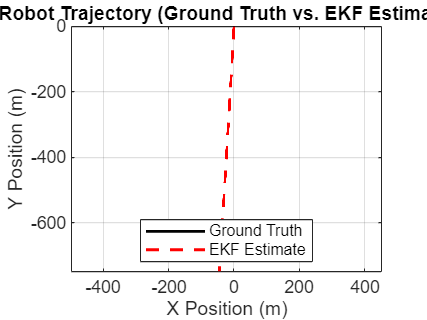

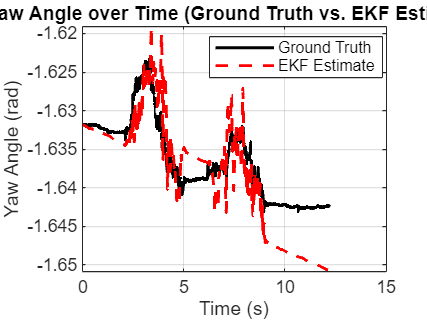

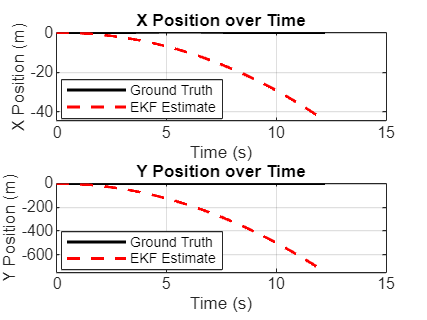

Plotting complete.


clc;clear;


function [X_Est, P_Est, GT] = myEKF(out)

    % --- Load Calibration Parameters ---
    calibParamFile = 'sensor_calibration_parameters.mat';
    try
        fprintf('Loading calibration parameters from: %s\n', calibParamFile);
        load(calibParamFile, 'calibrationParams');
        % Optional: Validate loaded structure has expected fields
        fprintf('Loaded Accel Bias (X,Y,Z): [%.6f, %.6f, %.6f]\n', calibrationParams.imu.accelBias);
        requiredFields = {'imu', 'tof'}; % Add 'mag' if used later
        if ~all(isfield(calibrationParams, requiredFields))
            error('Loaded calibrationParams structure is missing required fields.');
        end
        requiredIMUFields = {'gyroBias', 'accelBias'}; % Add variances if using directly in Q
        if ~all(isfield(calibrationParams.imu, requiredIMUFields))
             error('Loaded calibrationParams.imu structure is missing required fields.');
        end
         requiredToFFields = {'variance'};
        if ~all(isfield(calibrationParams.tof, requiredToFFields)) || length(calibrationParams.tof.variance) < 3
             error('Loaded calibrationParams.tof structure is missing required fields or has insufficient data.');
        end
        fprintf('Calibration parameters loaded successfully.\n');
    catch ME
        error('Failed to load or validate %s: %s\nPlease ensure the calibration script ran successfully and the file is accessible.', calibParamFile, ME.message);
    end
    % --- End Load Calibration Parameters ---

    % --- Configuration from Calibration (if needed) or Tunable ---
    % Example: Set forward axis based on calibration assumption or keep tunable
    F_idx = 2; % Forward Axis Index (determined from previous analysis)
    fprintf('Using Accelerometer Axis %d as forward axis.\n', F_idx);
    % Example: Scaling factor (still tunable based on previous findings)
    accel_scale_factor = -0.3; % (Values > 1.0 seemed necessary) - TUNE THIS
    fprintf('Using Accelerometer Scale Factor: %.2f\n', accel_scale_factor);

    % --- Data Extraction and Reshaping ---
    GT_position = out.GT_position.signals.values;
    GT_rotation = out.GT_rotation.signals.values;
    GT_time = out.GT_time.time;

    Sensor_ACCEL_val = squeeze(out.Sensor_ACCEL.signals.values);
    Sensor_ACCEL_time = out.Sensor_ACCEL.time;
    Sensor_GYRO_val = squeeze(out.Sensor_GYRO.signals.values);
    Sensor_GYRO_time = out.Sensor_GYRO.time;
    Sensor_ToF1_val = squeeze(out.Sensor_ToF1.signals.values);
    Sensor_ToF1_time = out.Sensor_ToF1.time;
    Sensor_ToF2_val = squeeze(out.Sensor_ToF2.signals.values);
    Sensor_ToF2_time = out.Sensor_ToF2.time;
    Sensor_ToF3_val = squeeze(out.Sensor_ToF3.signals.values);
    Sensor_ToF3_time = out.Sensor_ToF3.time;

    % --- Handle Potential Transpose Issues ---
    % (Ensuring data dimensions are Time x Channels)
    if ndims(Sensor_ACCEL_val) == 2 && size(Sensor_ACCEL_val, 2) ~= 3 && size(Sensor_ACCEL_val, 1) == 3, Sensor_ACCEL_val = Sensor_ACCEL_val'; end
    if size(Sensor_ACCEL_val, 2) == 3 && size(Sensor_ACCEL_val, 1) ~= length(Sensor_ACCEL_time), Sensor_ACCEL_val = Sensor_ACCEL_val'; end
    if ndims(Sensor_GYRO_val) == 2 && size(Sensor_GYRO_val, 2) ~= 3 && size(Sensor_GYRO_val, 1) == 3, Sensor_GYRO_val = Sensor_GYRO_val'; end
    if size(Sensor_GYRO_val, 2) == 3 && size(Sensor_GYRO_val, 1) ~= length(Sensor_GYRO_time), Sensor_GYRO_val = Sensor_GYRO_val'; end
    if ndims(Sensor_ToF1_val) == 2 && size(Sensor_ToF1_val, 2) ~= 4 && size(Sensor_ToF1_val, 1) == 4, Sensor_ToF1_val = Sensor_ToF1_val'; end
    if size(Sensor_ToF1_val, 2) == 4 && size(Sensor_ToF1_val, 1) ~= length(Sensor_ToF1_time), Sensor_ToF1_val = Sensor_ToF1_val'; end
    if ndims(Sensor_ToF2_val) == 2 && size(Sensor_ToF2_val, 2) ~= 4 && size(Sensor_ToF2_val, 1) == 4, Sensor_ToF2_val = Sensor_ToF2_val'; end
    if size(Sensor_ToF2_val, 2) == 4 && size(Sensor_ToF2_val, 1) ~= length(Sensor_ToF2_time), Sensor_ToF2_val = Sensor_ToF2_val'; end
    if ndims(Sensor_ToF3_val) == 2 && size(Sensor_ToF3_val, 2) ~= 4 && size(Sensor_ToF3_val, 1) == 4, Sensor_ToF3_val = Sensor_ToF3_val'; end
    if size(Sensor_ToF3_val, 2) == 4 && size(Sensor_ToF3_val, 1) ~= length(Sensor_ToF3_time), Sensor_ToF3_val = Sensor_ToF3_val'; end
    if size(GT_position, 2) == 3 && size(GT_position, 1) ~= length(GT_time), GT_position = GT_position'; end
    if size(GT_rotation, 2) == 4 && size(GT_rotation, 1) ~= length(GT_time), GT_rotation = GT_rotation'; end
    % --- End Data Extraction & Reshaping ---

    % --- Final Check on Data Dimensions ---
    if size(Sensor_ACCEL_val, 1) ~= length(Sensor_ACCEL_time), error('Final Check Failed: Accel data rows (%d) != time length (%d)', size(Sensor_ACCEL_val, 1), length(Sensor_ACCEL_time)); end
    if size(Sensor_GYRO_val, 1) ~= length(Sensor_GYRO_time), error('Final Check Failed: Gyro data rows (%d) != time length (%d)', size(Sensor_GYRO_val, 1), length(Sensor_GYRO_time)); end
    % Add similar checks for ToF if needed

    eul = quat2eul(GT_rotation);
    yaw_ground_truth = eul(:,1);
    GT = [GT_position(:,1), GT_position(:,2), yaw_ground_truth];

    num_steps = length(GT_time);
    num_states = 4; % x, y, yaw, v
    X_Est = zeros(num_steps, num_states);
    P_Est = zeros(num_states, num_states, num_steps);

    if isempty(GT) || size(GT,1) < 1, error('Ground truth data is empty or invalid. Cannot initialize EKF.'); end

    % --- Initialization ---
    X_hat = zeros(num_states, 1);
    X_hat(1) = GT(1,1); X_hat(2) = GT(1,2); X_hat(3) = GT(1,3); X_hat(4) = 0.0;
    P = diag([0.01^2, 0.01^2, (0.1*pi/180)^2, 0.1^2]); % Initial covariance
    X_Est(1,:) = X_hat';
    P_Est(:,:,1) = P;

    % --- Noise Parameters (Tune These!) ---
    % These remain tunable, but calibration variances can guide the tuning.
    q_xy_std = 0.05;
    % q_yaw_std informed by sqrt(gyroVariance(3)) -> sqrt(calib(Z) gyro var)
    q_yaw_std = 1.0*pi/180; % Example: Start with 1 deg/s std dev (TUNE)
    % q_v_std informed by sqrt(accelVariance(F_idx)) -> sqrt(calib(Fwd) accel var) * scale_factor?
    q_v_std = 0.1;          % Example: Start with 1.0 m/s^2 std dev (TUNE - was 0.5)
    % R_tof variance now comes directly from calibrationParams.tof.variance
    % R_tof_std = 0.08; % No longer used

    fprintf('EKF Tuning Noise Params: q_xy_std=%.3f, q_yaw_std=%.3f deg/s, q_v_std=%.3f\n', ...
             q_xy_std, rad2deg(q_yaw_std), q_v_std);
    fprintf('Information: sqrt(GyroZ Var)=%.3f deg/s, sqrt(Accel%d Var)=%.3f m/s^2\n', ...
            rad2deg(sqrt(calibrationParams.imu.gyroVariance(3))), F_idx, sqrt(calibrationParams.imu.accelVariance(F_idx)));

    Q = diag([q_xy_std^2, q_xy_std^2, q_yaw_std^2, q_v_std^2]);
    % R is now set dynamically in the update step using calibrated ToF variances

    % --- Constants ---
    X_max = 1.0; Y_max = 1.0; arena_dims = [0, X_max; 0, Y_max];
    tof1_offset = [0.1, 0]; tof2_offset = [0, 0.08]; tof3_offset = [0, -0.08];
    last_tof1_time = -Inf; last_tof2_time = -Inf; last_tof3_time = -Inf;
    default_dt = 1/200;

    % --- Main Loop ---
    for k = 2:num_steps
        % --- Time Step Calculation ---
        dt = GT_time(k) - GT_time(k-1);
        if dt <= 1e-6, dt = default_dt; end
        current_time = GT_time(k);

        % --- Get Inputs (Gyro and Accelerometer - CORRECTED) --- % MODIFIED SECTION
        gyro_z = 0; % Default if no new reading
        gyro_idx = find(Sensor_GYRO_time <= current_time, 1, 'last');
        if ~isempty(gyro_idx)
            gyro_raw = Sensor_GYRO_val(gyro_idx, :)'; % Raw 3x1 column
            gyro_corrected = gyro_raw - calibrationParams.imu.gyroBias; % Apply bias
            gyro_z = gyro_corrected(3); % Use Z component (assuming 3rd)
        end

        accel_x_body = 0; % Default
        accel_idx = find(Sensor_ACCEL_time <= current_time, 1, 'last');
        if ~isempty(accel_idx)
            accel_raw = Sensor_ACCEL_val(accel_idx, :)'; % Raw 3x1 column
            % --- Temporarily Disable Bias Correction ---
            % accel_corrected = accel_raw - calibrationParams.imu.accelBias; % COMMENT OUT
            accel_corrected = accel_raw; % USE RAW INSTEAD (TEMPORARILY)
            % --- End Temporary Change ---
            accel_x_body = accel_scale_factor * accel_corrected(F_idx);
        end
        % --- END MODIFIED INPUT SECTION ---

        % --- Prediction Step ---
        x_prev = X_hat(1); y_prev = X_hat(2); yaw_prev = X_hat(3); v_prev = X_hat(4);

        % Predict velocity using CORRECTED and SCALED accelerometer input
        v_pred = v_prev + accel_x_body * dt;

        % Predict position using PREVIOUS velocity
        x_pred = x_prev + v_prev * cos(yaw_prev) * dt;
        y_pred = y_prev + v_prev * sin(yaw_prev) * dt;

        % Predict yaw using CORRECTED gyro input
        yaw_pred = yaw_prev + gyro_z * dt;
        yaw_pred = wrapToPi(yaw_pred);

        X_pred = [x_pred; y_pred; yaw_pred; v_pred]; % Predicted state vector

        % Calculate State Transition Jacobian (F - 4x4) - Unchanged
        F = eye(num_states);
        F(1, 3) = -v_prev * sin(yaw_prev) * dt; F(1, 4) = cos(yaw_prev) * dt;
        F(2, 3) =  v_prev * cos(yaw_prev) * dt; F(2, 4) = sin(yaw_prev) * dt;
        F(4,4) = 1; % Included for clarity, handled by eye(4)

        P_pred = F * P * F' + Q; % Predicted covariance

        % --- Update Step (Process Measurements) ---
        z_meas = [];
        z_pred_vec = [];
        H_list = [];
        R_indices = []; % Store index (1, 2, or 3) of ToF sensor for R

        % Process ToF1
        if ~isempty(Sensor_ToF1_time) && ~isempty(Sensor_ToF1_val)
            tof1_idx = find(Sensor_ToF1_time <= current_time & Sensor_ToF1_time > last_tof1_time, 1, 'last');
            if ~isempty(tof1_idx)
                 current_tof1_val = Sensor_ToF1_val(tof1_idx, :);
                 meas_tof1 = current_tof1_val(1); status_tof1 = current_tof1_val(4);
                 if (status_tof1 == 2 || status_tof1 == 4) && meas_tof1 < 1.5 && meas_tof1 > 0.02
                     [z_p, H_i] = predict_measurement_and_jacobian(X_pred, tof1_offset, 0, arena_dims, num_states);
                     if ~isnan(z_p) && ~any(isnan(H_i), 'all')
                        z_meas = [z_meas; meas_tof1]; z_pred_vec = [z_pred_vec; z_p];
                        H_list = [H_list; H_i]; R_indices = [R_indices; 1]; % Add index 1
                     end
                 end
                 last_tof1_time = Sensor_ToF1_time(tof1_idx);
            end
        end

        % Process ToF2
        if ~isempty(Sensor_ToF2_time) && ~isempty(Sensor_ToF2_val)
           tof2_idx = find(Sensor_ToF2_time <= current_time & Sensor_ToF2_time > last_tof2_time, 1, 'last');
            if ~isempty(tof2_idx)
               current_tof2_val = Sensor_ToF2_val(tof2_idx, :);
               meas_tof2 = current_tof2_val(1); status_tof2 = current_tof2_val(4);
                if (status_tof2 == 2 || status_tof2 == 4) && meas_tof2 < 1.5 && meas_tof2 > 0.02
                    [z_p, H_i] = predict_measurement_and_jacobian(X_pred, tof2_offset, pi/2, arena_dims, num_states);
                     if ~isnan(z_p) && ~any(isnan(H_i), 'all')
                       z_meas = [z_meas; meas_tof2]; z_pred_vec = [z_pred_vec; z_p];
                       H_list = [H_list; H_i]; R_indices = [R_indices; 2]; % Add index 2
                     end
                end
                last_tof2_time = Sensor_ToF2_time(tof2_idx);
            end
        end

        % Process ToF3
        if ~isempty(Sensor_ToF3_time) && ~isempty(Sensor_ToF3_val)
            tof3_idx = find(Sensor_ToF3_time <= current_time & Sensor_ToF3_time > last_tof3_time, 1, 'last');
            if ~isempty(tof3_idx)
                current_tof3_val = Sensor_ToF3_val(tof3_idx, :);
                meas_tof3 = current_tof3_val(1); status_tof3 = current_tof3_val(4);
                if (status_tof3 == 2 || status_tof3 == 4) && meas_tof3 < 1.5 && meas_tof3 > 0.02
                    [z_p, H_i] = predict_measurement_and_jacobian(X_pred, tof3_offset, -pi/2, arena_dims, num_states);
                     if ~isnan(z_p) && ~any(isnan(H_i), 'all')
                       z_meas = [z_meas; meas_tof3]; z_pred_vec = [z_pred_vec; z_p];
                       H_list = [H_list; H_i]; R_indices = [R_indices; 3]; % Add index 3
                     end
                end
                last_tof3_time = Sensor_ToF3_time(tof3_idx);
            end
        end

        % --- Measurement Fusion --- % MODIFIED R CALCULATION
        R_scale = 3;
        if ~isempty(z_meas)
            H = H_list;
            % --- Use calibrated ToF variances based on sensors used ---
            if isempty(R_indices)
                warning('myEKF:UpdateNoR', 'Measurements available but no ToF indices tracked for R at k=%d.', k);
                 % Fallback: Use average or default if indices aren't tracked properly
                 R_diag_vals = R_scale * repmat(mean(calibrationParams.tof.variance), size(H, 1), 1);
            else
                 % --- THIS IS WHERE THE VALUES FOR R ARE TAKEN FROM ---
                 R_diag_vals = R_scale * calibrationParams.tof.variance(R_indices); % Get variances for used sensors
                 % --- END WHERE VALUES ARE TAKEN ---
            end
            % --- THIS IS WHERE R IS CREATED ---
            R = diag(R_diag_vals); % Build diagonal R matrix MxM

            y = z_meas - z_pred_vec;         % Innovation (Mx1)
            S = H * P_pred * H' + R;        % Innovation covariance (MxM)

            try
                S_inv = inv(S); K = P_pred * H' * S_inv; X_hat = X_pred + K * y;
                X_hat(3) = wrapToPi(X_hat(3)); % Wrap yaw
                I = eye(num_states); P = (I - K * H) * P_pred; P = (P + P') / 2; % Ensure symmetry
            catch ME
                 warning('myEKF:UpdateFailed', 'Kalman update failed at k=%d: %s. Using prediction.', k, ME.message);
                 X_hat = X_pred; P = P_pred;
            end
        else % No valid measurements
            X_hat = X_pred; P = P_pred;
        end

        % --- Store Results ---
        X_Est(k,:) = X_hat';
        P_Est(:,:,k) = P;
    end % End main loop (k)

end % End function myEKF


% --- Helper Function: predict_measurement_and_jacobian ---
% (No changes needed in this helper function)
function [z_pred, H] = predict_measurement_and_jacobian(x_state, sensor_offset_body, sensor_angle_body, arena_dims, num_states)
    x = x_state(1); y = x_state(2); yaw = x_state(3);
    H = nan(1, num_states); z_pred = nan;
    R_mat = [cos(yaw) -sin(yaw); sin(yaw) cos(yaw)];
    sensor_offset_global = R_mat * sensor_offset_body(:);
    sensor_pos = [x; y] + sensor_offset_global;
    sensor_angle_global = wrapToPi(yaw + sensor_angle_body);
    [z_pred_nominal, ~] = ray_cast(sensor_pos, sensor_angle_global, arena_dims);
    if isnan(z_pred_nominal) || isinf(z_pred_nominal), return; end
    z_pred = z_pred_nominal;
    delta = 1e-7; H_calc = zeros(1, num_states); valid_H = true;
    for i = 1:num_states
        perturbation = zeros(num_states,1); perturbation(i) = delta;
        x_state_perturbed = x_state + perturbation;
        x_p = x_state_perturbed(1); y_p = x_state_perturbed(2); yaw_p = wrapToPi(x_state_perturbed(3));
        if i <= 3
            R_mat_p = [cos(yaw_p) -sin(yaw_p); sin(yaw_p) cos(yaw_p)];
            sensor_offset_global_p = R_mat_p * sensor_offset_body(:);
            sensor_pos_p = [x_p; y_p] + sensor_offset_global_p;
            sensor_angle_global_p = wrapToPi(yaw_p + sensor_angle_body);
            [z_p, ~] = ray_cast(sensor_pos_p, sensor_angle_global_p, arena_dims);
        else, z_p = z_pred_nominal; end
        if isnan(z_p) || isinf(z_p), valid_H = false; break;
        else, H_calc(i) = (z_p - z_pred_nominal) / delta; end
    end
    if valid_H && ~any(isinf(H_calc)) && ~any(isnan(H_calc)), H = H_calc;
    else, H = nan(1, num_states); z_pred = nan; end
end

% --- Helper Function: ray_cast (remains unchanged) ---
function [distance, hit_point] = ray_cast(origin, angle, arena_dims)
    ox = origin(1); oy = origin(2); c = cos(angle); s = sin(angle);
    x_min = arena_dims(1,1); x_max = arena_dims(1,2); y_min = arena_dims(2,1); y_max = arena_dims(2,2);
    distances = []; points = []; tiny = 1e-9;
    if abs(c) > tiny
        t_xmax = (x_max - ox) / c; if t_xmax >= -tiny, y_hit = oy + t_xmax * s; if y_hit >= y_min - tiny && y_hit <= y_max + tiny, distances = [distances, t_xmax]; points = [points; x_max, y_hit]; end, end
        t_xmin = (x_min - ox) / c; if t_xmin >= -tiny, y_hit = oy + t_xmin * s; if y_hit >= y_min - tiny && y_hit <= y_max + tiny, distances = [distances, t_xmin]; points = [points; x_min, y_hit]; end, end
    end
    if abs(s) > tiny
        t_ymax = (y_max - oy) / s; if t_ymax >= -tiny, x_hit = ox + t_ymax * c; if x_hit >= x_min - tiny && x_hit <= x_max + tiny, distances = [distances, t_ymax]; points = [points; x_hit, y_max]; end, end
        t_ymin = (y_min - oy) / s; if t_ymin >= -tiny, x_hit = ox + t_ymin * c; if x_hit >= x_min - tiny && x_hit <= x_max + tiny, distances = [distances, t_ymin]; points = [points; x_hit, y_min]; end, end
    end
    if isempty(distances), distance = nan; hit_point = [nan, nan];
    else
        valid_indices = find(distances >= 0); if isempty(valid_indices), distance = nan; hit_point = [nan, nan];
        else
           positive_distances = distances(valid_indices); [min_dist, min_idx_in_valid] = min(positive_distances); original_idx = valid_indices(min_idx_in_valid);
           if min_dist < 1e-6, distance = nan; hit_point = [nan, nan]; else, distance = min_dist; hit_point = points(original_idx, :); end
        end
    end
end

Run

data = load('trainingData/task1_5.mat');
out = data.out;

[X_Est, P_Est, GT] = myEKF(out);


Eval

% Load data (assuming 'out' is already loaded from the .mat file)
% data = load('trainingData/task1_5.mat');
% out = data.out;

% Run EKF (assuming myEKF function is available)
% [X_Est, P_Est, GT_from_EKF] = myEKF(out); % GT_from_EKF is Nx3 [x,y,yaw]

fprintf('Starting Evaluation Script...\n');

% ------------------ Extract Data ------------------ %
pos_GT_orig   = out.GT_position.signals.values;
rot_GT_quat_wxyz = out.GT_rotation.signals.values; % w,x,y,z format
timeVec  = out.GT_time.time;

if isrow(timeVec), timeVec = timeVec'; end
fprintf('Extracted GT Position, Rotation, and Time.\n');

% --- Handle Potential Transpose Issues ---
if size(pos_GT_orig, 2) ~= 3 && size(pos_GT_orig, 1) == 3, pos_GT_orig = pos_GT_orig'; fprintf('Transposed original GT position data.\n'); end
if size(rot_GT_quat_wxyz, 2) ~= 4 && size(rot_GT_quat_wxyz, 1) == 4, rot_GT_quat_wxyz = rot_GT_quat_wxyz'; fprintf('Transposed original GT rotation data.\n'); end
% --- End Transpose Handling ---

% ------------------ Ensure Consistent Lengths ------------------ %
N_gt_pos = size(pos_GT_orig, 1); N_gt_rot = size(rot_GT_quat_wxyz, 1);
N_time = length(timeVec); N_est = size(X_Est, 1);
N = min([N_gt_pos, N_gt_rot, N_time, N_est]);

if N < max([N_gt_pos, N_gt_rot, N_time, N_est])
    fprintf('--- Warning: Truncating data lengths from max(%d, %d, %d, %d) to shortest N = %d ---\n', N_gt_pos, N_gt_rot, N_time, N_est, N);
    pos_GT = pos_GT_orig(1:N, :); rot_GT_quat_wxyz = rot_GT_quat_wxyz(1:N, :);
    timeVec = timeVec(1:N); X_Est = X_Est(1:N, :);
else
    fprintf('--- Data lengths consistent: N = %d ---\n', N);
    pos_GT = pos_GT_orig;
end
if N == 0, error('Effective data length is zero after checking consistency.'); end

% ------------------ Convert Ground Truth Rotation to Yaw ------------------ %
fprintf('Converting Ground Truth rotation to Yaw (N=%d)...\n', N);
yaw_GT = zeros(N, 1); valid_gt_quat = true(N, 1);
for i = 1:N
    try
        qGT = quaternion(rot_GT_quat_wxyz(i,1), rot_GT_quat_wxyz(i,2), rot_GT_quat_wxyz(i,3), rot_GT_quat_wxyz(i,4));
        qGT = normalize(qGT); eulGT = eulerd(qGT, 'ZYX', 'frame'); yaw_GT(i) = deg2rad(eulGT(1));
    catch ME_gt_conv, warning('Error converting GT quaternion at index %d: %s.', i, ME_gt_conv.message); yaw_GT(i) = NaN; valid_gt_quat(i) = false; end
end
yaw_GT = wrapToPi(yaw_GT);
fprintf('Ground Truth Yaw conversion complete.\n');

% ------------------ Get Estimated Yaw ------------------ %
if size(X_Est, 2) < 3, error('X_Est does not contain Yaw data.'); end
yaw_Est = wrapToPi(X_Est(:, 3));
fprintf('Extracted Estimated Yaw.\n');

% ------------------ Convert Poses to rigidtform3d (Optional) --- %
fprintf('Converting poses to rigidtform3d arrays (N=%d)...\n', N);
gtTforms(N) = rigidtform3d; estTforms(N) = rigidtform3d;
for i = 1:N
     if valid_gt_quat(i) && ~any(isnan(pos_GT(i,:)))
        qGT = quaternion(rot_GT_quat_wxyz(i,1:4)); qGT = normalize(qGT); RGT = rotmat(qGT, 'frame'); tGT = pos_GT(i,1:min(3,end));
        if length(tGT) == 2, tGT = [tGT, 0]; end; gtTforms(i) = rigidtform3d(RGT, tGT(:)');
     else, gtTforms(i) = rigidtform3d(); end
    if ~any(isnan(X_Est(i, 1:2))) && ~isnan(yaw_Est(i))
        tEst = [X_Est(i, 1), X_Est(i, 2), 0]; yaw_est_i = yaw_Est(i);
        REst = [cos(yaw_est_i), -sin(yaw_est_i), 0; sin(yaw_est_i), cos(yaw_est_i), 0; 0, 0, 1];
        estTforms(i) = rigidtform3d(REst, tEst);
    else, estTforms(i) = rigidtform3d(); end
end
fprintf('Pose conversions complete.\n');


% ------------------ Compare Trajectories & Calculate Key RMSEs --- % % MODIFIED SECTION
fprintf('\n--- Trajectory Comparison Results ---\n');

% --- Run compareTrajectories if possible (Optional) ---
metrics = []; canCompare = false;
try % Version/Toolbox check
    v = ver('MATLAB'); versionYear = str2double(regexp(v.Release, 'R(\d{4})[ab]', 'tokens', 'once'));
    if ~isempty(versionYear) && (versionYear >= 2024)
        reqToolbox = 'Navigation Toolbox'; allInstalledToolboxes = ver;
        if any(strcmp({allInstalledToolboxes.Name}, reqToolbox)), canCompare = true; fprintf('MATLAB version/toolbox OK for compareTrajectories.\n');
        else, fprintf('Required toolbox (%s) not found for compareTrajectories.\n', reqToolbox); end
    else, fprintf('MATLAB version might be too old for compareTrajectories.\n'); end
catch ME_ver, warning('Could not determine MATLAB version reliably: %s', ME_ver.message); end

if ~canCompare, warning('compareTrajectories requires specific MATLAB version/toolbox. Skipping.');
else % Attempt to run compareTrajectories
    try
        validIdx = arrayfun(@(x) ~isequal(x.Rotation, eye(3)), estTforms) & arrayfun(@(x) ~isequal(x.Rotation, eye(3)), gtTforms);
        if sum(validIdx) < 2, warning('Not enough valid transforms (%d) to run compareTrajectories.', sum(validIdx));
        else
            metrics = compareTrajectories(estTforms(validIdx), gtTforms(validIdx), 'AlignmentType', 'rigid');
            fprintf('compareTrajectories executed (Specific metrics below are calculated manually).\n');
            % Optional plotting from metrics object can remain if desired
            % try, figure('Name', 'compareTrajectories Plot'); plot(metrics, "absolute-translation"); title('Absolute Translation Error (compareTrajectories)'); grid on; catch plotME, warning('Failed to plot metrics: %s', plotME.message); end
        end
    catch ME_compare, warning('Failed to execute compareTrajectories: %s', ME_compare.message); end
end
% --- End Optional compareTrajectories ---

% --- Calculate and Print Manual Position and Yaw Absolute RMSE --- % ADDED BACK
% Position RMSE (Manual Calculation)
valid_pos_idx = ~isnan(X_Est(:, 1)) & ~isnan(X_Est(:, 2)) & ~isnan(pos_GT(:, 1)) & ~isnan(pos_GT(:, 2));
if sum(valid_pos_idx) > 0 && size(X_Est, 2) >= 2 && size(pos_GT, 2) >= 2
    pos_err_x = X_Est(valid_pos_idx, 1) - pos_GT(valid_pos_idx, 1);
    pos_err_y = X_Est(valid_pos_idx, 2) - pos_GT(valid_pos_idx, 2);
    squared_pos_err = pos_err_x.^2 + pos_err_y.^2;
    rmse_position = sqrt(mean(squared_pos_err));
    fprintf('Position Absolute RMSE (Manual) (m):     %.4f\n', rmse_position); % Output this
else
    fprintf('Position Absolute RMSE (Manual) (m):     Cannot calculate.\n');
    rmse_position = NaN;
end

% Yaw RMSE (Manual Calculation)
valid_yaw_idx = ~isnan(yaw_Est) & ~isnan(yaw_GT);
if sum(valid_yaw_idx) > 0
    yaw_error = wrapToPi(yaw_Est(valid_yaw_idx) - yaw_GT(valid_yaw_idx));
    squared_yaw_err = yaw_error.^2;
    rmse_yaw_rad = sqrt(mean(squared_yaw_err));
    rmse_yaw_deg = rad2deg(rmse_yaw_rad);
    fprintf('Yaw Absolute RMSE (Manual) (degrees):    %.4f\n', rmse_yaw_deg); % Output this
else
    fprintf('Yaw Absolute RMSE (Manual) (degrees):    Cannot calculate.\n');
    rmse_yaw_deg = NaN;
end
% --- End Manual RMSE Calculation & Print ---

fprintf('--- End Trajectory Comparison Results ---\n\n');
% --- END MODIFIED SECTION ---


% ------------------ Plot Position Comparison (Subplots) ------------------ %
fprintf('Plotting Position: Ground Truth (Left) vs Estimate (Right)...\n');
figure('Name', 'Position Comparison');
all_x = [pos_GT(:,1); X_Est(:,1)]; all_y = [pos_GT(:,2); X_Est(:,2)];
x_lim = [min(all_x) max(all_x)]; y_lim = [min(all_y) max(all_y)];
x_range = diff(x_lim); y_range = diff(y_lim); margin = 0.05;
x_lim = x_lim + [-x_range*margin, x_range*margin]; y_lim = y_lim + [-y_range*margin, y_range*margin];
if x_range == 0, x_lim = x_lim + [-0.1, 0.1]; end; if y_range == 0, y_lim = y_lim + [-0.1, 0.1]; end

subplot(1, 2, 1); % GT Position
plot(pos_GT(:,1), pos_GT(:,2), 'b-', 'LineWidth', 1.5);
title('Ground Truth Position'); xlabel('X Position (m)'); ylabel('Y Position (m)');
xlim(x_lim); ylim(y_lim); axis equal; grid on;

subplot(1, 2, 2); % Est Position
plot(X_Est(:,1), X_Est(:,2), 'r--', 'LineWidth', 1.5);
title('EKF Estimated Position'); xlabel('X Position (m)'); ylabel('Y Position (m)');
xlim(x_lim); ylim(y_lim); axis equal; grid on;

try, sgtitle('Position Comparison: Ground Truth (Left) vs EKF Estimate (Right)'); catch, disp('sgtitle unavailable.'); end


% ------------------ Plot Yaw Comparison (Subplots) ------------------ %
fprintf('Plotting Yaw: Ground Truth (Left) vs Estimate (Right)...\n');
figure('Name', 'Yaw Comparison');
if sum(valid_yaw_idx) > 0
    unwrapped_yaw_gt_deg = rad2deg(unwrap(yaw_GT(valid_yaw_idx))); unwrapped_yaw_est_deg = rad2deg(unwrap(yaw_Est(valid_yaw_idx)));
    all_yaw_deg = [unwrapped_yaw_gt_deg; unwrapped_yaw_est_deg]; y_lim_yaw = [min(all_yaw_deg) max(all_yaw_deg)];
    y_range_yaw = diff(y_lim_yaw); y_lim_yaw = y_lim_yaw + [-y_range_yaw*margin, y_range_yaw*margin];
    if y_range_yaw == 0, y_lim_yaw = y_lim_yaw + [-10, 10]; end

    subplot(1, 2, 1); % GT Yaw
    plot(timeVec(valid_yaw_idx), unwrapped_yaw_gt_deg, 'b-', 'LineWidth', 1.5);
    title('Ground Truth Yaw'); xlabel('Time (s)'); ylabel('Unwrapped Yaw Angle (degrees)'); ylim(y_lim_yaw); grid on;

    subplot(1, 2, 2); % Est Yaw
    plot(timeVec(valid_yaw_idx), unwrapped_yaw_est_deg, 'r--', 'LineWidth', 1.5);
    title('EKF Estimated Yaw'); xlabel('Time (s)'); ylabel('Unwrapped Yaw Angle (degrees)'); ylim(y_lim_yaw); grid on;

    try, sgtitle('Yaw Comparison: Ground Truth (Left) vs EKF Estimate (Right)'); catch, disp('sgtitle unavailable.'); end
else, subplot(1,1,1); title('Yaw Comparison (No valid data to plot)'); end


% ------------------ Plot Yaw Error ------------------ %
fprintf('Plotting Yaw Estimation Error...\n');
figure('Name', 'Yaw Estimation Error');
if sum(valid_yaw_idx) > 0
    yaw_error_deg = rad2deg(wrapToPi(yaw_Est(valid_yaw_idx) - yaw_GT(valid_yaw_idx)));
    plot(timeVec(valid_yaw_idx), yaw_error_deg, 'k-', 'LineWidth', 1);
    xlabel('Time (s)'); ylabel('Yaw Error (degrees)'); title('Yaw Estimation Error (EKF - Ground Truth)'); grid on;
    max_err = max(abs(yaw_error_deg));
    if ~isnan(max_err) && max_err > 0, ylim([-max(1, max_err*1.1), max(1, max_err*1.1)]); end
else, title('Yaw Estimation Error (No valid data to plot)'); end

fprintf('--- End of Evaluation Script ---\n');

helper

data = load('trainingData/task1_3.mat');
out = data.out;
GT_position = out.GT_position.signals.values;
GT_rotation = out.GT_rotation.signals.values;
GT_time = out.GT_time.time;

Sensor_ACCEL_val = squeeze(out.Sensor_ACCEL.signals.values);
Sensor_ACCEL_time = out.Sensor_ACCEL.time;
Sensor_GYRO_val = squeeze(out.Sensor_GYRO.signals.values);
Sensor_GYRO_time = out.Sensor_GYRO.time;
Sensor_ToF1_val = squeeze(out.Sensor_ToF1.signals.values);
Sensor_ToF1_time = out.Sensor_ToF1.time;
Sensor_ToF2_val = squeeze(out.Sensor_ToF2.signals.values);
Sensor_ToF2_time = out.Sensor_ToF2.time;
Sensor_ToF3_val = squeeze(out.Sensor_ToF3.signals.values);
Sensor_ToF3_time = out.Sensor_ToF3.time;
fprintf('Checking dimensions before plotting accelerometer data:\n');
% Make sure variables exist and are numeric
if ~exist('Sensor_ACCEL_time', 'var') || ~isnumeric(Sensor_ACCEL_time)
    error('Sensor_ACCEL_time does not exist or is not numeric.');
end
if ~exist('Sensor_ACCEL_val', 'var') || ~isnumeric(Sensor_ACCEL_val)
     error('Sensor_ACCEL_val does not exist or is not numeric.');
end

fprintf('Size of Sensor_ACCEL_time: %s\n', mat2str(size(Sensor_ACCEL_time)));
fprintf('Size of Sensor_ACCEL_val: %s\n', mat2str(size(Sensor_ACCEL_val)));

% --- Attempt to Fix Dimension Mismatch ---
num_time_points = length(Sensor_ACCEL_time);

% Check if Sensor_ACCEL_val likely needs transpose
if size(Sensor_ACCEL_val, 1) ~= num_time_points
    fprintf('Row count of Sensor_ACCEL_val (%d) does not match length of Sensor_ACCEL_time (%d).\n', size(Sensor_ACCEL_val, 1), num_time_points);
    if size(Sensor_ACCEL_val, 2) == num_time_points
        fprintf('Attempting to transpose Sensor_ACCEL_val...\n');
        Sensor_ACCEL_val = Sensor_ACCEL_val';
        fprintf('New size of Sensor_ACCEL_val: %s\n', mat2str(size(Sensor_ACCEL_val)));
    else
        error('Cannot resolve dimension mismatch between Sensor_ACCEL_time and Sensor_ACCEL_val for plotting.');
    end
end

% --- Final check after potential transpose ---
if size(Sensor_ACCEL_val, 1) ~= num_time_points
     error('Dimension mismatch persists after attempting transpose.');
end

% Ensure we have at least one column to plot in Accel data
if size(Sensor_ACCEL_val, 2) < 1
    error('Sensor_ACCEL_val appears to have zero columns after processing.');
end

figure;
subplot(3, 1, 1); % Plot Axis 1 (the one you already plotted)
plot(Sensor_ACCEL_time(:), Sensor_ACCEL_val(:, 1));
ylabel('Accel Axis 1'); title('Accelerometer Readings'); grid on;

if size(Sensor_ACCEL_val, 2) >= 2
    subplot(3, 1, 2); % Plot Axis 2
    plot(Sensor_ACCEL_time(:), Sensor_ACCEL_val(:, 2));
    ylabel('Accel Axis 2'); grid on;
end

if size(Sensor_ACCEL_val, 2) >= 3
    subplot(3, 1, 3); % Plot Axis 3 (likely Z/Gravity)
    plot(Sensor_ACCEL_time(:), Sensor_ACCEL_val(:, 3));
    ylabel('Accel Axis 3'); xlabel('Time (s)'); grid on;
end
